clear; clc; close all;

syms G X I U D
Gb = 4.5;
Ib = 15;
P1 = 0;
P2 = 0.025;
P3 = 0.000013;
V = 12;
n = 5.54/60;
F = [ -P1*G-X*(G+Gb)+D;
      -P2*X+P3*I;
      -n*(I+Ib)+U/V ];
y = G;

St = [G;X;I];
In = [U;D];

## Equilibrium State


% sol_s = solve(subs(F,{D},{0})==[0;0;0], [G,X,I]);
% Ge = sol_s.G; Ie = sol_s.I; Xe = sol_s.X;
St_e = [0;0;0];
In_e = [n*Ib*V;0];
Fe = subs(subs(F,In,In_e),St,St_e);

## Linearize


% f(x) = f(xe,ue) + (grad(f,x)|x=xe,u=ue)*(x-xe) + (grad(f,u)|x=xe,u=ue)*(u-ue)
grad_F_St = [ diff(F(1),St(1)), diff(F(1),St(2)), diff(F(1),St(3));
              diff(F(2),St(1)), diff(F(2),St(2)), diff(F(2),St(3));
              diff(F(3),St(1)), diff(F(3),St(2)), diff(F(3),St(3)) ];
grad_F_In = [ diff(F,In(1)) , diff(F,In(2)) ];
A = double(subs(subs(grad_F_St,In,In_e),St,St_e))

A =          0   -4.5000         0
         0   -0.0250    0.0000
         0         0   -0.0923


B = double(subs(subs(grad_F_In,In,In_e),St,St_e))

B =          0    1.0000
         0         0
    0.0833         0


C = [1,0,0]

C =      1     0     0


D = 0

D = 0

## Transfer Function


syms s
n = size(A,1);
Gp = C*inv(s*eye(n)-A)*B;
ExpFun = matlabFunction(simplifyFraction(Gp,'Expand',true));
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gp = tf(ExpFun(tf('s')));
for i = 1:length(Gp)
    [num,den] = tfdata(Gp(i));
    Gp(i) = tf(num{1}/den{1}(1),den{1}/den{1}(1));
end
Gp = Gp(1)


Gp =
 
           -4.875e-06
  -----------------------------
  s^3 + 0.1173 s^2 + 0.002308 s
 
Continuous-time transfer function.



[Gp_Num, Gp_Den] = tfdata(Gp);

Gp_Num = 1×1 cell array
    {1×4 double}


## Analog Control


Gc = pidtune(Gp,'PID')


Gc =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -22.7, Ki = -0.0995, Kd = -1e+03
 
Continuous-time PID controller in parallel form.



trans_info = stepinfo(feedback(series(Gc,Gp),1))

trans_info = struct with fields:
        RiseTime: 29.3956
    SettlingTime: 405.7572
     SettlingMin: 0.9186
     SettlingMax: 1.0793
       Overshoot: 7.9320
      Undershoot: 0
            Peak: 1.0793
        PeakTime: 66.0147


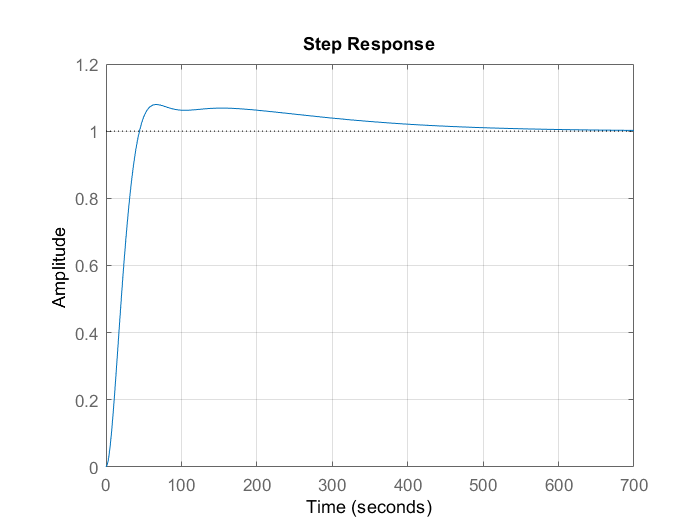

step(feedback(series(Gc,Gp),1))
grid on

## Digital Control

% 2 < tr/Ts < 10
Ts = trans_info.RiseTime/8;
Gd_1 = c2d(Gc,Ts,'tastin')


Gd_1 =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = -22.7, Ki = -0.0995, Kd = -1e+03, Ts = 3.67
 
Sample time: 3.6745 seconds
Discrete-time PID controller in parallel form.



Gd_2 = c2d(Gc,Ts,'matched')


Gd_2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = -23.1, Ki = -0.0994, Kd = -1.04e+03, Ts = 3.67
 
Sample time: 3.6745 seconds
Discrete-time PID controller in parallel form.



Discrete Transfer Function( p4 )

Gp_d = c2d(Gp,Ts,'zoh')


Gp_d =
 
  -3.626e-05 z^2 - 0.0001305 z - 2.923e-05
  ----------------------------------------
     z^3 - 2.625 z^2 + 2.274 z - 0.6498
 
Sample time: 3.6745 seconds
Discrete-time transfer function.



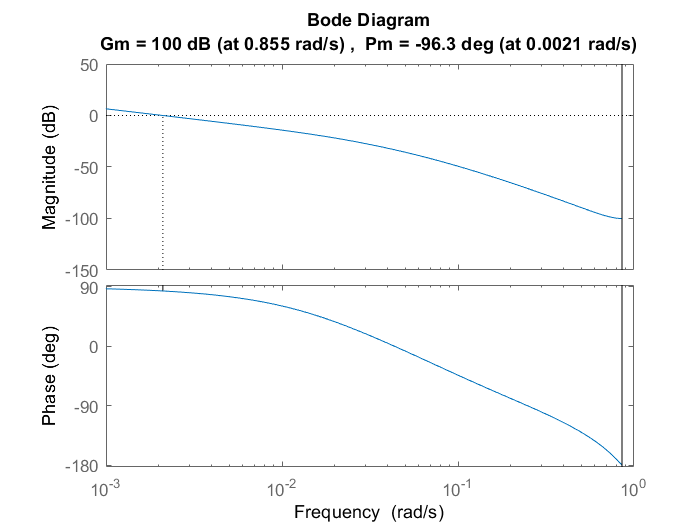

margin(Gp_d)

[Gp_d_Num, Gp_d_Den] = tfdata(Gp_d);
Gp_d_Num{1} 

ans =    1.0e-03 *

         0   -0.0363   -0.1305   -0.0292


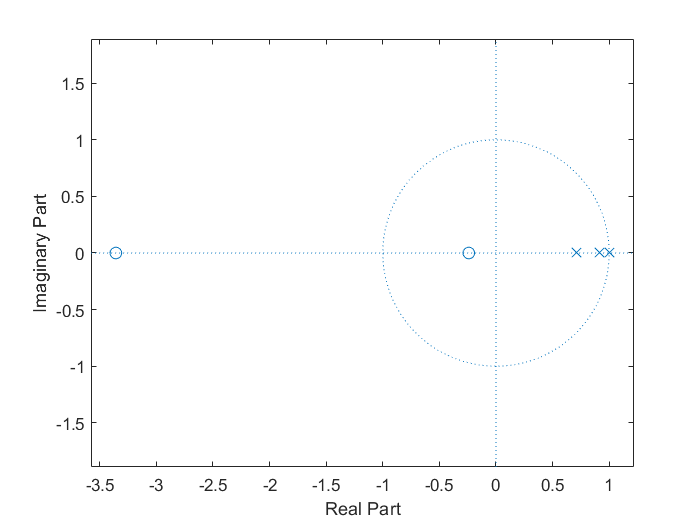

zplane(Gp_d_Num{1} , Gp_d_Den{1})

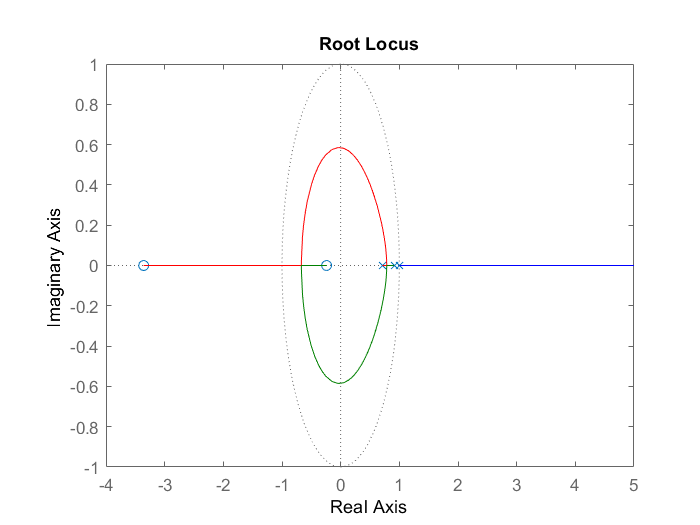


rlocus(Gp_d)

Design a Discrete controller (p5)

4/

[z,p,k] = tf2zp(Gp_d_Num{1},Gp_d_Den{1})

z =    -3.3583
   -0.2400


p =     1.0000
    0.9122
    0.7123


k = -3.6259e-05